# mlxkit showcase

MATLAB code running in **GNU Octave** through the mlxkit Jupyter kernel — no MATLAB needed. Every output below was produced by running this notebook with the kernel *MATLAB (Octave · mlxkit)*.

This notebook was also converted into a MATLAB live script, `showcase.mlx`, with all outputs placed on the lines that produced them (`mlx build showcase.ipynb`).

## 1 · One workspace across cells

Like MATLAB's Live Editor, all cells share one workspace. These variables are used further down.

g = 9.81;      % gravity [m/s^2]
v0 = 20;       % launch speed [m/s]
angle = 45;    % launch angle [deg]
range = v0^2 * sind(2*angle) / g

range = 40.7747

## 2 · Outputs look like MATLAB's

Statements without a semicolon show their value. Scalars, text, matrices, logical arrays, structs and cell arrays are each displayed as the matching MATLAB output type, so they keep their type when the notebook becomes an `.mlx`.

speed = 12.5

speed = 12.5000

name = 'Octave'

name = 'Octave'

M = magic(4)

M = 16    2    3   13
 5   11   10    8
 9    7    6   12
 4   14   15    1


mask = M > 8

mask = 1  0  0  1
0  1  1  0
1  0  0  1
0  1  1  0


car.model = 'sedan';
car.mass = 1420;
car.wheelbase = 2.7;
car

car = struct with fields:
        model: 'sedan'
         mass: 1420
    wheelbase: 2.7000


parts = {'wheel', 4, [1 2 3]}

parts = 1×3 cell array
    {'wheel'}    {[4]}    {[1 2 3]}


## 3 · Figures

Figures appear under the cell that drew them. MATLAB's `'Interpreter','latex'` labels are translated into Octave's TeX subset, so `$x$`, `$v_0$` and Greek letters still render.

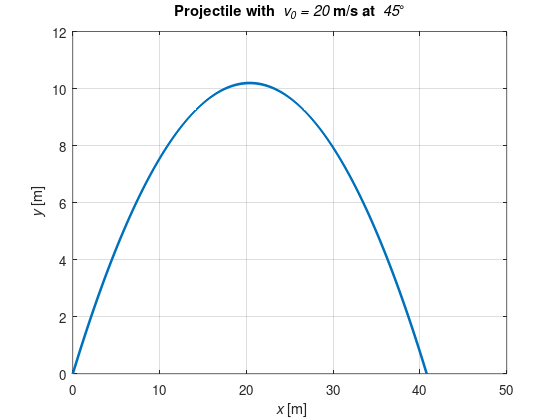

t = linspace(0, 2*v0*sind(angle)/g, 200);
x = v0*cosd(angle)*t;
y = v0*sind(angle)*t - g*t.^2/2;
plot(x, y, 'LineWidth', 2); grid on
xlabel('$x$ [m]', 'Interpreter', 'latex')
ylabel('$y$ [m]', 'Interpreter', 'latex')
title('Projectile with $v_0 = 20$ m/s at $45^\circ$', 'Interpreter', 'latex')

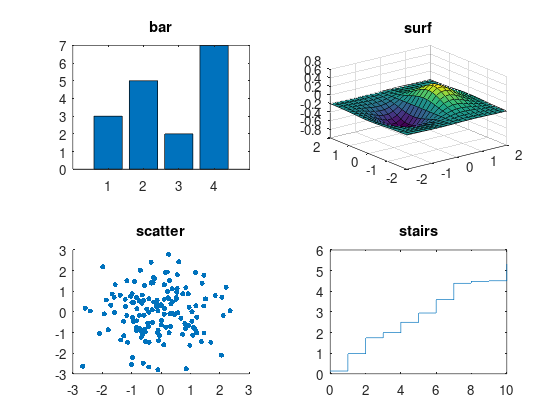

figure
rng(1)
subplot(2,2,1); bar([3 5 2 7]); title('bar')
subplot(2,2,2); [X, Y] = meshgrid(-2:0.2:2); surf(X, Y, X.*exp(-X.^2 - Y.^2)); title('surf')
subplot(2,2,3); scatter(randn(150,1), randn(150,1), 15, 'filled'); title('scatter')
subplot(2,2,4); stairs(0:10, cumsum(rand(1,11))); title('stairs')

## 4 · Newer MATLAB syntax, rewritten for Octave

Octave doesn't understand several things recent MATLAB versions allow. mlxkit rewrites them before running, so the code stays plain MATLAB:

- name=value arguments: `plot(x, y, LineWidth=3)`

- string concatenation: `"Range: " + r + " m"`

- graphics objects with dot notation: `ax.FontSize = 13`, `h.XData(end)`

- `tiledlayout` / `nexttile`

- `arguments` blocks in functions, with default values

- extra parameters passed through ODE solvers: `ode45(f, tspan, y0, opts, p1, p2)`

- MATLAB-only defaults such as `set(groot, 'defaultLegendInterpreter', ...)`

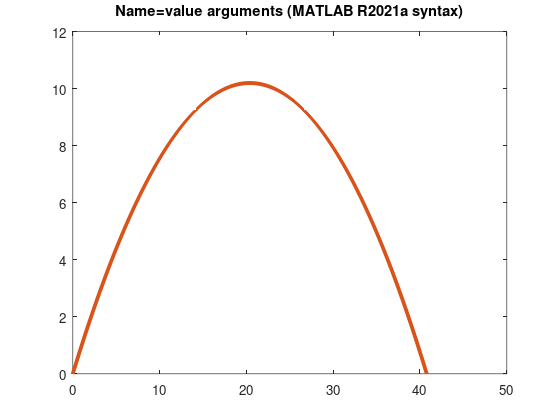

figure
plot(x, y, LineWidth=3, Color=[0.85 0.33 0.10])
title("Name=value arguments (MATLAB R2021a syntax)")

n = numel(t);
disp("Simulated " + n + " time steps")

Simulated 200 time steps


summary = "Range: " + round(range*10)/10 + " m"

summary = 'Range: 40.8 m'

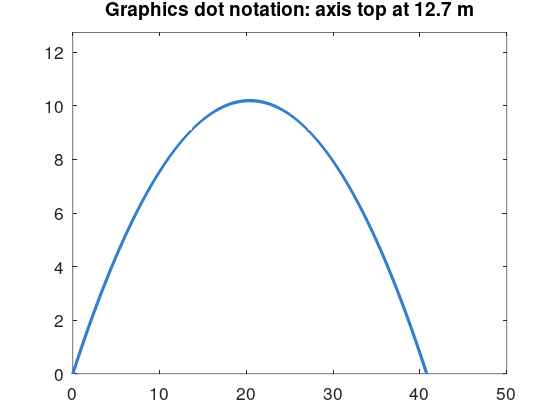

figure
h = plot(x, y);
ax = gca;
ax.FontSize = 13;
h.LineWidth = 2.5;
h.Color = [0.2 0.5 0.8];
ax.YLim = [0, 1.25*max(y)];
title(sprintf('Graphics dot notation: axis top at %.1f m', ax.YLim(2)))

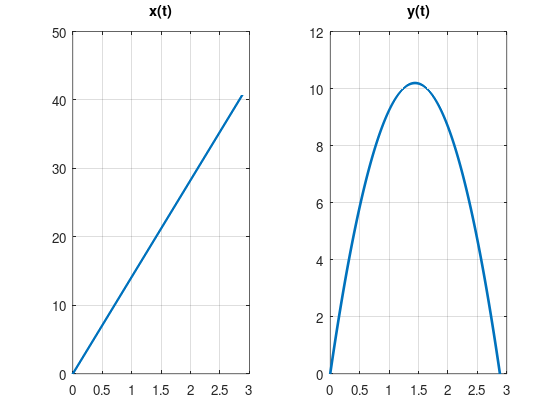

figure
tiledlayout(1, 2)
nexttile; plot(t, x, 'LineWidth', 2); title('x(t)'); grid on
nexttile; plot(t, y, 'LineWidth', 2); title('y(t)'); grid on

Local functions can be defined in any cell and used afterwards. When the notebook becomes an `.mlx`, these cells move to the end of the live script, where MATLAB requires them.

euclidean = pnorm(3, 4)

euclidean = 5

manhattan = pnorm(3, 4, 1)

manhattan = 7

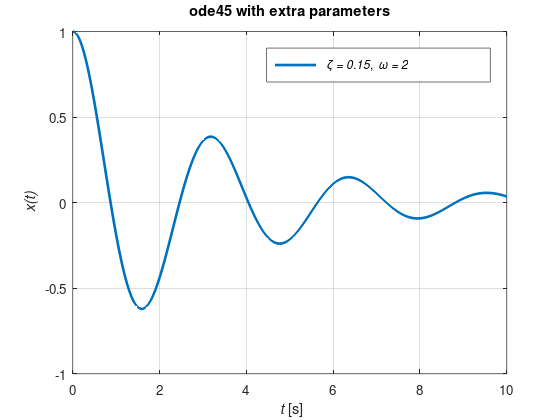

set(groot, 'defaultLegendInterpreter', 'latex')   % MATLAB-only default: safely ignored
[tt, yy] = ode45(@oscillator, [0 10], [1 0], odeset('RelTol', 1e-6), 0.15, 2);
figure
plot(tt, yy(:,1), 'LineWidth', 2); grid on
xlabel('$t$ [s]', 'Interpreter', 'latex'); ylabel('$x(t)$', 'Interpreter', 'latex')
legend('$\zeta = 0.15$, $\omega = 2$', 'Interpreter', 'latex')
title('ode45 with extra parameters')

## 5 · Warnings, errors and streaming output

Warnings are shown and the cell keeps going. An error stops the cell, like in MATLAB, but the workspace survives. Text appears as each statement finishes, so long cells aren't silent.

warning('Step size is large; results may be inaccurate')

disp('...the cell keeps running after a warning')

...the cell keeps running after a warning


disp('starting a slow computation'); pause(1)

starting a slow computation


disp('half way there'); pause(1)

half way there


disp('done')

done


result = undefined_function(42)

'undefined_function' undefined near line 1, column 10

% the workspace is still intact after the error
fprintf('range is still %.2f m\n', range)

range is still 40.77 m


## 6 · Interactive features

These don't show in a saved notebook, but try them:

- **Interrupt** (■ in the toolbar) stops a long computation; the workspace is kept. Try `k = 0; while true, k = k + 1; end`, interrupt it, then `k`.

- **Restart kernel** clears the workspace and starts a fresh Octave.

- **Tab** completes variable and function names; **Shift+Tab** shows `help`.

## 7 · Back to a MATLAB live script

- `mlx notebook script.mlx` turns a live script into a notebook

- `mlx build script.ipynb` turns the notebook back into the live script, outputs included

- `mlx run script.mlx` runs a live script directly in Octave (it stops at the first error, like MATLAB)

- `mlx html script.mlx` shows a live script with its outputs in a browser

function d = pnorm(x, y, p)
    arguments
        x double
        y double
        p (1,1) double = 2      % default: Euclidean
    end
    d = (abs(x).^p + abs(y).^p).^(1/p);
end

function dydt = oscillator(t, y, zeta, w)
    dydt = [y(2); -2*zeta*w*y(2) - w^2*y(1)];
end